# MXB226 Case Study Modelling an Electronic Component

## Full Storage

load full_storage;
%Solving using cholesky factorisation, then forward and backward substitution
tic;
A = cholesky(A);
Choleksy_Full_Storage_Runtime = toc;
temperatures = forward_substitution(A', b);
temperatures = backward_substitution(A, temperatures);

Visualisating the Temperature from Full Storage

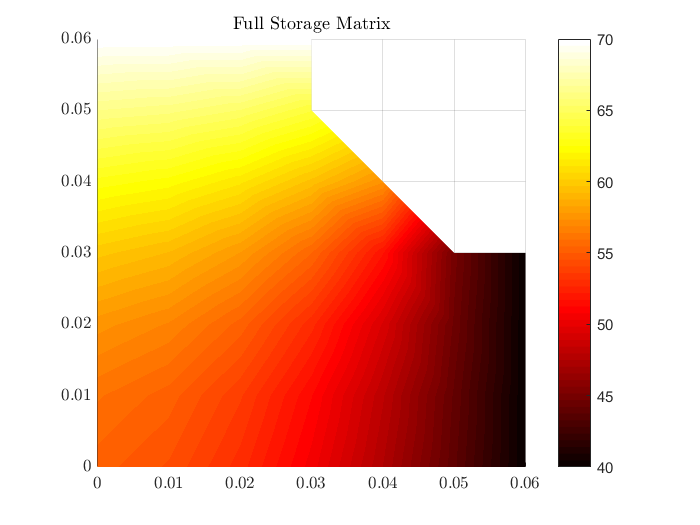

visualisation(temperatures, 'Full Storage Matrix')

## Packed Storage

load full_storage
%NOT CORRECT, NEED TO FIX FORWARD AND BACK SUBS
a = packed_storage(A);
tic;
a = Cholesky_Packed(a);
Cholesky_Packed_Runtime = toc;
temperatures = packed_forward_substitution(a, b);
temperatures = packed_backward_substitution(a, temperatures);

Visualisating the Temperature from Packed Storage

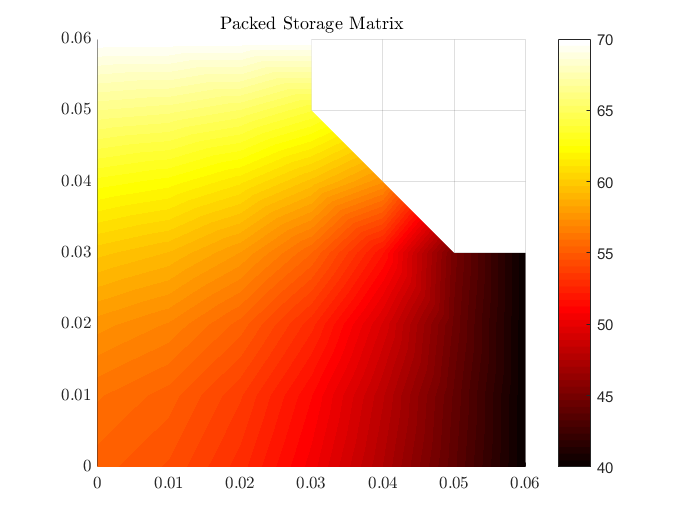

visualisation(temperatures, 'Packed Storage Matrix')

## Band Storage

%RCM Storage
load full_storage
%Create a new matrix to work with
A_RCM = A;
%create ordering vector
p= symrcm(A_RCM);
%order the A matrix and b vector according the RCM storage
A_RCM = A_RCM(p,p);
b_rcm = b(p);
reorder = reorder_vector(p);
%Create a band storage for A
A_band = band(A_RCM);
%Perform cholesky factorisation on the banded matrix
tic;
G_Band_then_chol = cholesky_band(A_band, 8);
Choleksy_Band_Runtime = toc;

%solve with forward substitution and then backwards substitution

temperatures = banded_forward_substitution(G_Band_then_chol, b_rcm);
temperatures = banded_backward_substitution(G_Band_then_chol, temperatures);
temperatures = temperatures(reorder);
%Visualisating the Temperature from Band Storage

Visualise the temperatures

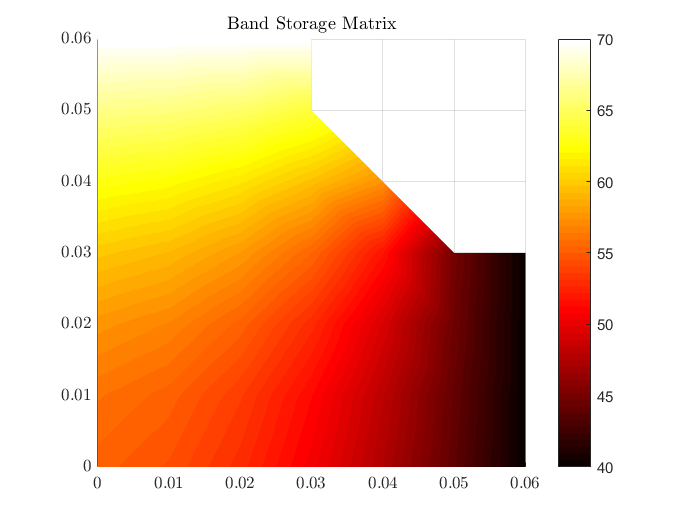

visualisation(temperatures, 'Band Storage Matrix')

## Sparse Storage

[temperatures, Cholesky_Sparsed_Runtime] = sparseStorage(A, b);

Visualisating the Temperature from Sparse Storage

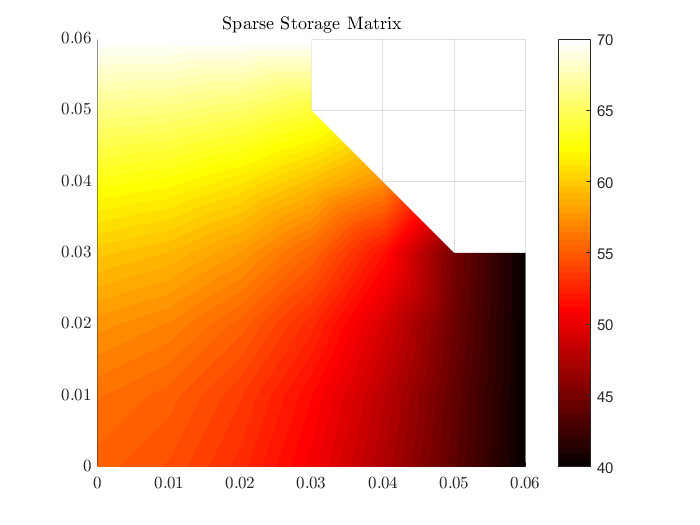

visualisation(temperatures, 'Sparse Storage Matrix')

## CSR Storage

clear rb;
[r,c,v] = find(A);
[r_sorted,order] = sort(r);
c = c(order);
v = v(order);

r_current = r_sorted(1);
count = 0;
rb = 1;

for i = 1:length(r_sorted)
    count = count + 1;
    if (r_sorted(i) ~= r_current)
        rb = [rb, count];
        r_current = r_sorted(i);
    end
end

% rb ends with nz + 1, where nz is the total number of nonzero elements in A.
rb = [rb, count + 1];

n = size(A, 1);
x0 = ones(n, 1)*10;
tol = 1e-5;
maxiters = 1000;

Solve CSR Using Jacobi Method

tic;
[temperatures, ~, ~, ~] = jacobi_CSR(rb, c', v', b, x0, tol, maxiters);
Jacobi_Runtime = toc;

Visualisating the Temperature from Jacobi CSR Storage

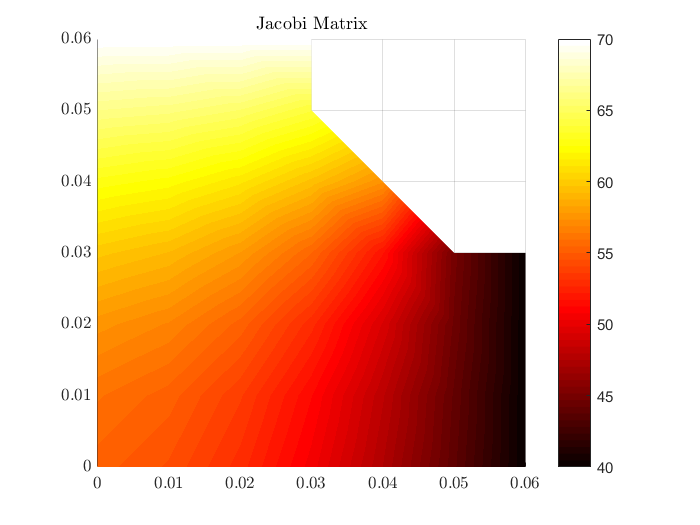

visualisation(temperatures, 'Jacobi Matrix')

Solve CSR Using Gauss Seidel Method

tic;
[temperatures, ~, ~, ~] = gauss_seidel_CSR(rb, c', v', b, x0, tol, maxiters);
Gauss_Seidel_Runtime = toc;

Visualisating the Temperature from Gauss Seidel CSR Storage

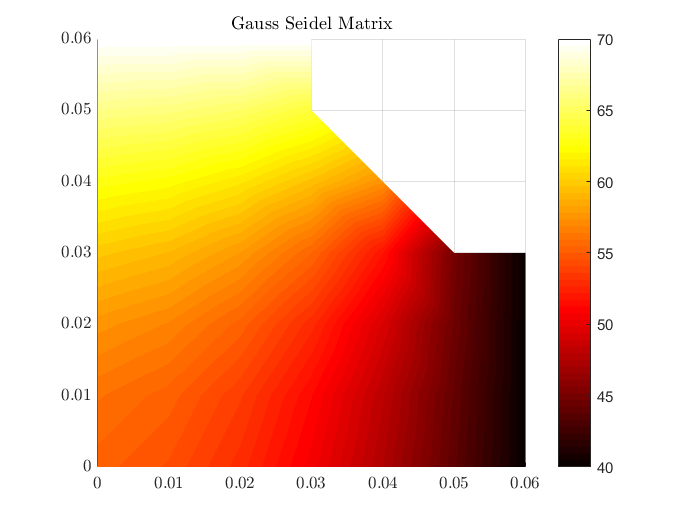

visualisation(temperatures, 'Gauss Seidel Matrix')

Solve CSR Using Conjugate Gradient Method

tic;
[temperatures, ~, ~, ~] = conjugate_gradient_CSR(rb, c', v', b, x0, tol, maxiters);
Conjugate_Gradient_Runtime = toc;

Visualisating the Temperature from Conjugate Gradient CSR Storage

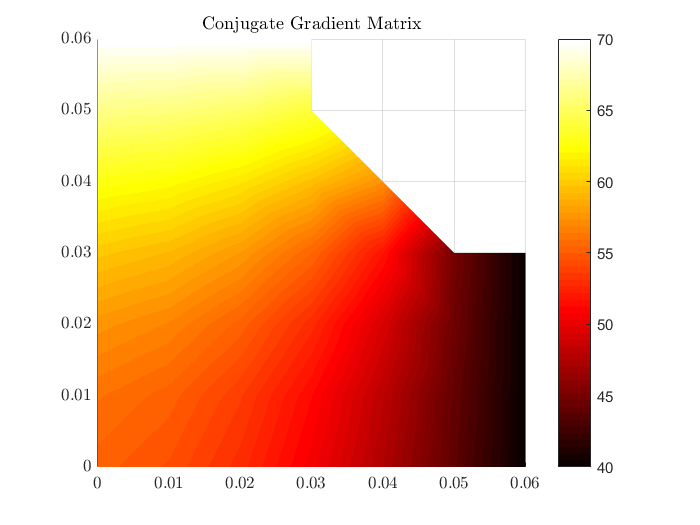

visualisation(temperatures, 'Conjugate Gradient Matrix')

Solve CSR Using SOR Method

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));

tic;
[temperatures, ~, ~, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters);
SOR_Runtime = toc;

Visualisating the Temperature from SOR CSR Storage

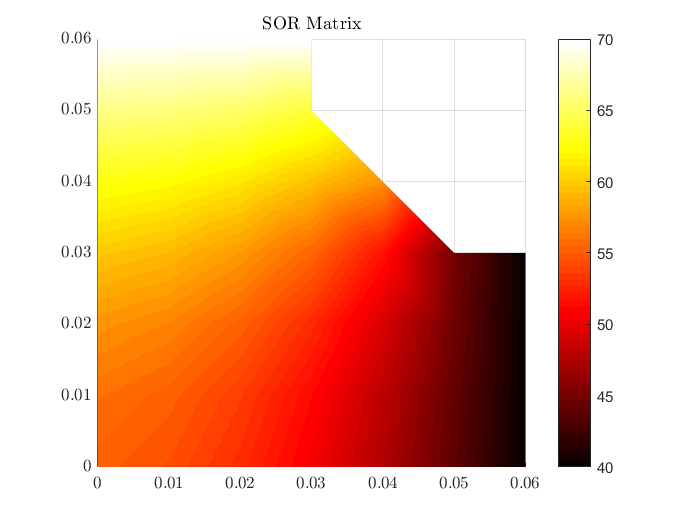

visualisation(temperatures, 'SOR Matrix')

## Efficiency Comparison

Bandwidth and level of fill-in for each different Node Ordering

%ffgdfh

Memory (for direct Methods), Iterations (for Iterative Methods), Runtime (Direct and Iterative), Floating Point Operations (direct and iterative).

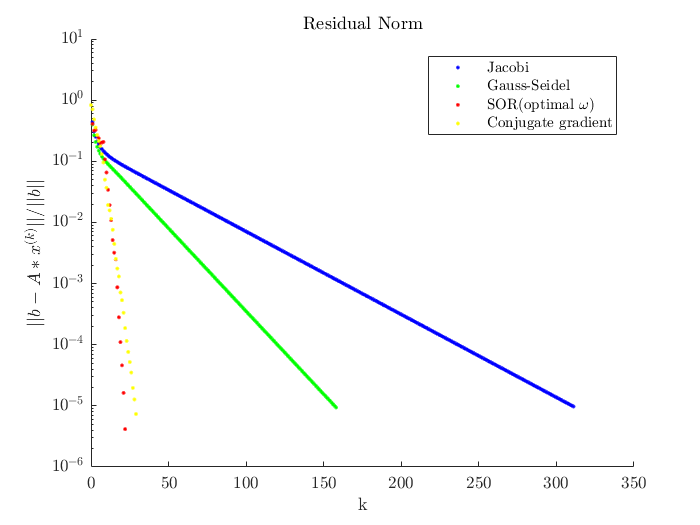

%Iterations
[~, ~, jacobi_k, jacobi_res] = jacobi_CSR(rb, c', v', b, x0, tol, maxiters);
[~, ~, gs_k, gs_res] = gauss_seidel_CSR(rb, c', v', b, x0, tol, maxiters);
[~, ~, conjugate_k, conjugate_res] = conjugate_gradient_CSR(rb, c', v', b, x0, tol, maxiters);
[~, ~, SOR_k, SOR_res] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters);

figure
hold on
set(gca, 'Yscale', 'log');
ylim([1e-6 10]);
plot(0:jacobi_k, jacobi_res, 'b.');
plot(0:gs_k, gs_res, 'g.');
plot(0:conjugate_k, conjugate_res, 'r.');
plot(0:SOR_k, SOR_res, 'y.');
title('Residual Norm', 'Interpreter', 'latex')
set(gca,'TickLabelInterpreter','latex')

lgd = legend('Jacobi', 'Gauss-Seidel', 'SOR(optimal $\omega$)', 'Conjugate gradient');
lgd.Interpreter = 'latex';

ylabel('$||b-A*x^{(k)}|| / ||b||$', 'Interpreter','latex')
xlabel('k', 'Interpreter','latex')


%Runtime
Choleksy_Full_Storage_Runtime

Choleksy_Full_Storage_Runtime = 0.2343

Cholesky_Packed_Runtime

Cholesky_Packed_Runtime = 0.0141

Choleksy_Band_Runtime

Choleksy_Band_Runtime = 0.0119

Cholesky_Sparsed_Runtime

Cholesky_Sparsed_Runtime = 1.8290e-04

Jacobi_Runtime

Jacobi_Runtime = 0.0444

Gauss_Seidel_Runtime

Gauss_Seidel_Runtime = 0.0355

Conjugate_Gradient_Runtime

Conjugate_Gradient_Runtime = 0.0272

SOR_Runtime

SOR_Runtime = 0.0334

Tolerance that is required for the iterative method to produce a solution that is visually indistinguishable from that produced by the direct methods.

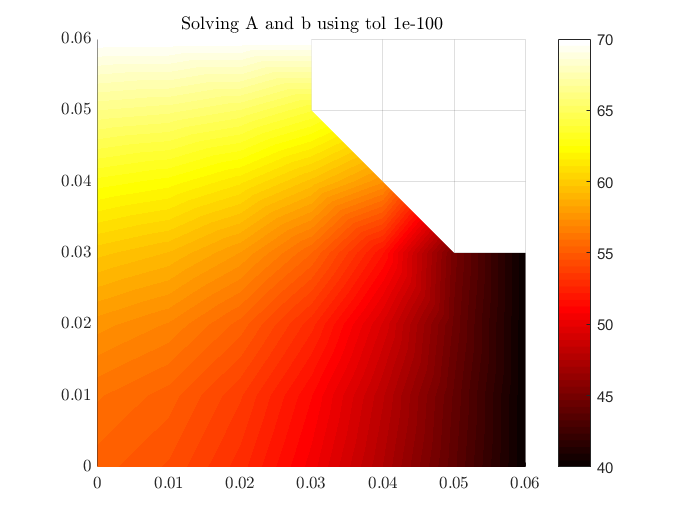

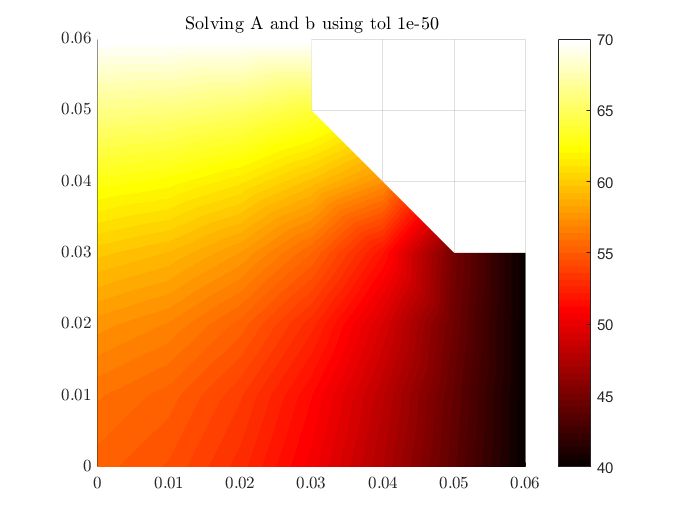

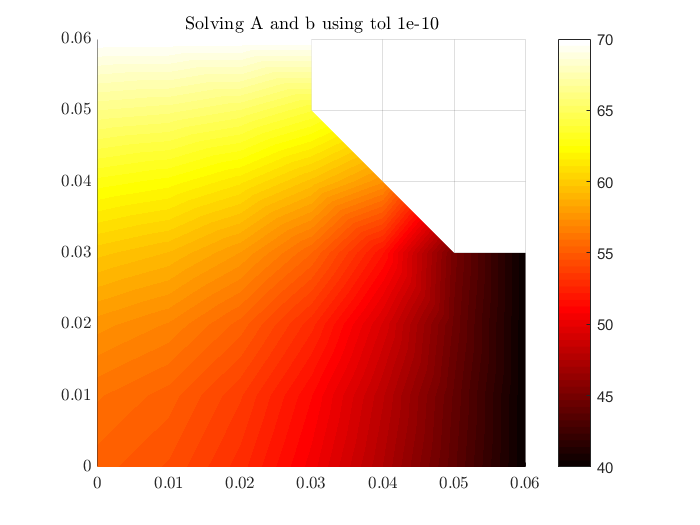

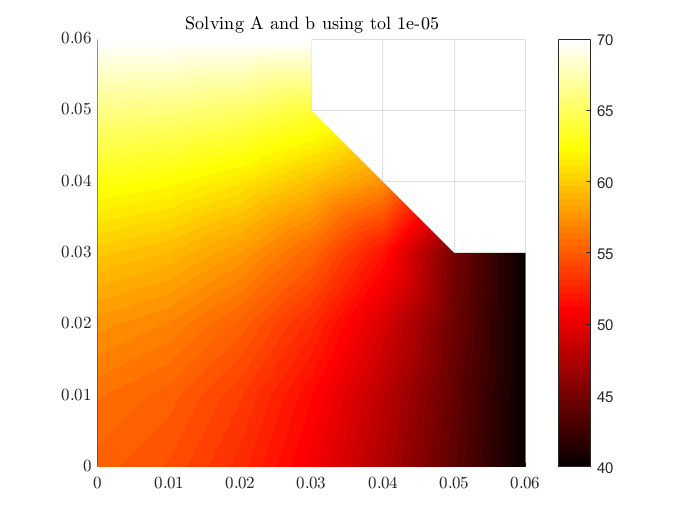

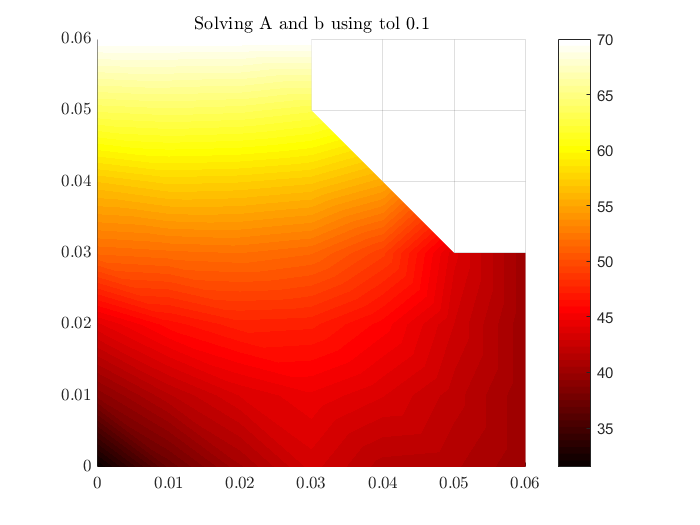

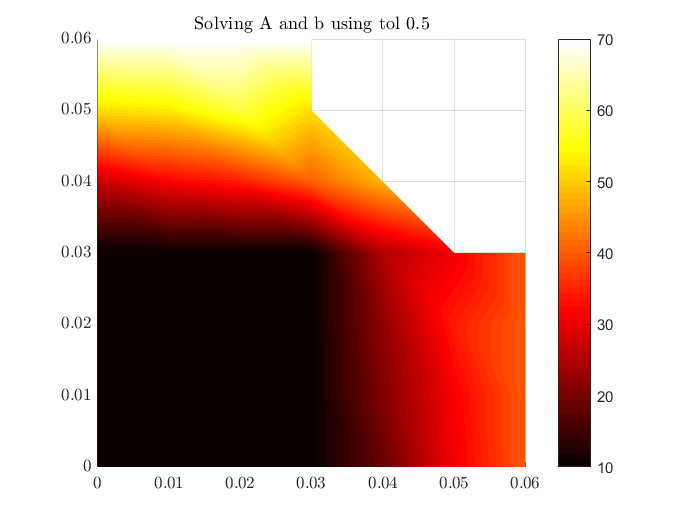

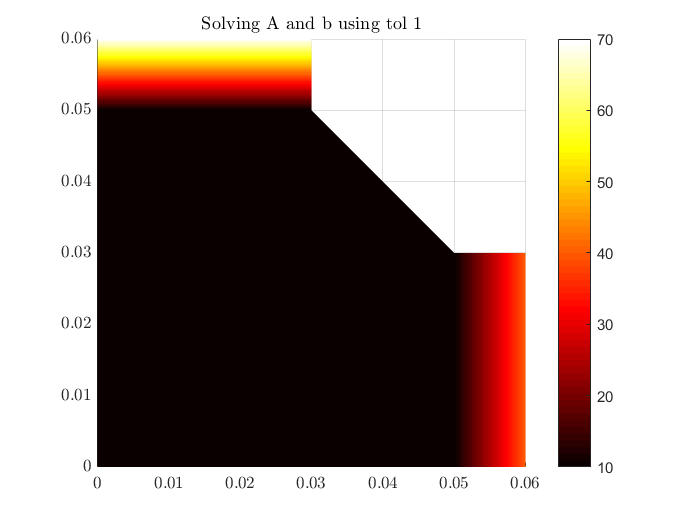

tolVec = [1e-100, 1e-50, 1e-10, 1e-5, 1e-1, 0.5, 1];
[~,n] = size(tolVec);

for i = 1:n
    [temperatures, ~, ~, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tolVec(i), maxiters);
    graphTitle = ['Solving A and b using tol ', num2str(tolVec(i)), ''];
    visualisation(temperatures, graphTitle)
end

Effect of w on the rate of convergence of the SOR method.

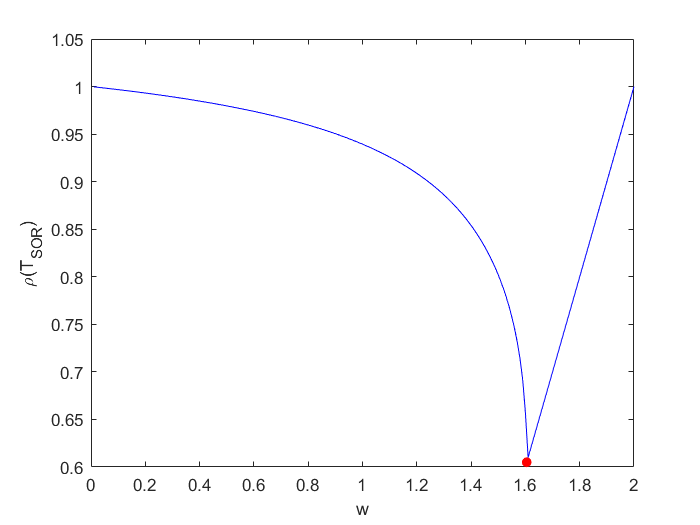

D = diag(diag(A));
L = tril(A, -1);
U = triu(A, 1);
T_J = - (D \ (L + U));
rhoT_J = max(abs(eig(T_J)));
w_opt = (2 /(1 + sqrt(1 - rhoT_J^2)));
T_SOR_opt = (D/w_opt + L) \ ((1-w_opt)/w_opt * D - U);
rhoT_SOR_opt = max(abs(eig(T_SOR_opt)));

wVec = linspace(1e-2,2,200);
rhoT_SOR = zeros(1,200);

for i = 1:200
    w = wVec(i);
    T_SOR = (D/w + L) \ ((1-w)/w * D - U);
    rhoT_SOR(i) = max(abs(eig(T_SOR)));
end

figure;
plot(wVec, rhoT_SOR, 'b')
hold on
plot(w_opt, rhoT_SOR_opt,'r.','Markersize',20);
ylabel('\rho(T_{SOR})')
xlabel('w')

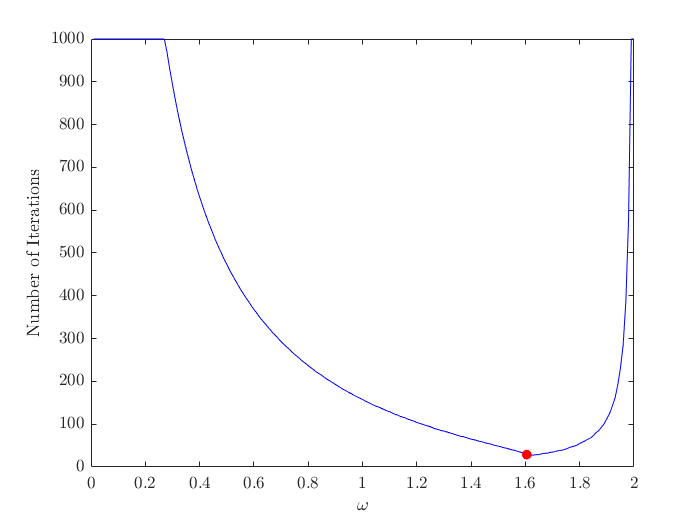


kVec = zeros(1,200);
[~, ~, k_opt, ~] = sor_CSR(rb, c', v', b, x0, w_opt, tol, maxiters);

for i = 1:200
    [~, ~, kVec(i), ~] = sor_CSR(rb, c', v', b, x0, wVec(i), tol, maxiters);
end

figure;
plot(wVec, kVec, 'b')
hold on
plot(w_opt, k_opt,'r.','Markersize',20);
ylabel('Number of Iterations', 'Interpreter','latex')
xlabel('$\omega$', 'Interpreter','latex')
set(gca,'TickLabelInterpreter','latex')